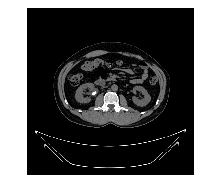

I = imread('Stone- (11).jpeg');
imshow(I);

I = rgb2gray(I)

I = 512×512 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

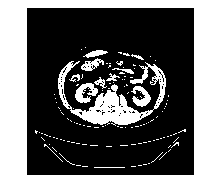

binaryI = I>80;
imshow(binaryI)

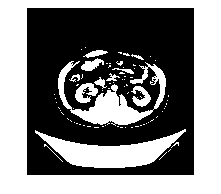


%fill in holes
binaryI = imfill(binaryI, 'holes');
imshow(binaryI)


% Get region properties
stats = regionprops(binaryI, 'Area');

%declare the area range you want to keep and not filter
minArea = 2000;
maxArea = 2850;
%adds label to each connected object 
labels = bwlabel(binaryI)

labels =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

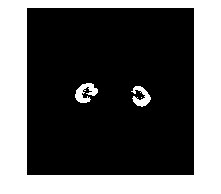

%filter based on area range checks for each one that they fit inside the
% area
binaryI = ismember(labels, find([stats.Area] >= minArea & [stats.Area] <= maxArea));
%display the result of segmented kidneys
imshow(binaryI)


%overlay mask of kidneys over original image
overlayedimage = labeloverlay(I,binaryI)

overlayedimage = 512×512×3 uint8 array
overlayedimage(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

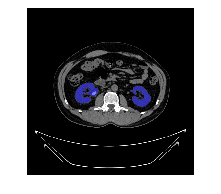

imshow(overlayedimage);


% Get region properties
stats = regionprops(binaryI, 'BoundingBox')

stats = 2×1 struct array with fields:
    BoundingBox


boundingboxcoords_leftkidney = stats(1).BoundingBox

boundingboxcoords_leftkidney =   147.5000  229.5000   72.0000   63.0000


boundingboxcoords_rightkidney = stats(2).BoundingBox

boundingboxcoords_rightkidney =   317.5000  238.5000   62.0000   64.0000




%%binarize original image to isolate anything bright white to get kidney stones
%and compare if mask of kidney stones is in same location as kidney mask
% if it matches then it is kidney stone
